# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Patricia Cuesta Ruiz y Laura Mambrilla Moreno**

**Fecha: 21/11/2021**

clc;
clear all;
close all;

# Tema 4. Ejercicio 1 - Operaciones morfológicas 

1) Lee la Imagen

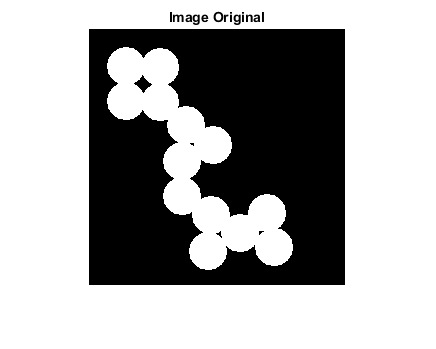

imgOriginal = imread('circles.png');

figure;
imshow(imgOriginal);
title('Image Original');

2) Crea un elemento estructurante. 

 se = strel('disk', 5);

3) Realiza operaciones morfológicas en la imagen.

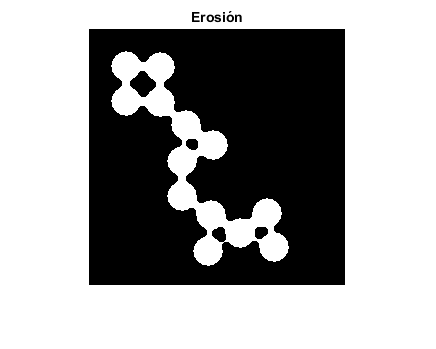

erodeBW = imerode(imgOriginal,se);
figure;
imshow(erodeBW);
title('Erosión');

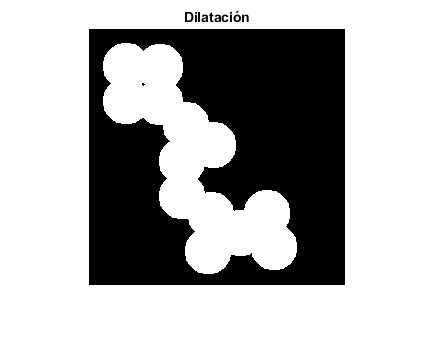

dilateBW = imdilate(imgOriginal,se);
figure;
imshow(dilateBW);
title('Dilatación');

Se pide: 

- Ejecute el código anterior para la imagen binaria `'circles.png'`, la imagen en escala de grises `'rice.png' `y la imagen en color `'autumn.tif'`. ¿Qué diferencias ve en el comportamiento de los operadores morfológicos para las distintas imágenes?

- Elementos estructurantes: Observe el efecto de las operaciones morfológicas utilizadas en (3) con  elementos estructurantes de diferentes formas/tamaños (ver ayuda: [https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).](https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).)

- Operadores morfológicos. Cargue la imagen en escala de grises `'rice.png' `y realice una operación de umbralizado con la función `imbinarize`, que por defecto utiliza el método de Otsu. Utilice las funciones `imclose` o `imopen` para eliminar los pequeños píxeles aislados que puedan estar en el fondo de la imagen. Tenga en cuenta que el tipo y tamaño del elemento estructural debe ser ajustado.

- Repita la pregunta anterior pero utilizando la imagen original complementada (utilice la función `imcomplement`) y compare el resultado de las operaciones.

% close all
% clear all

Paso 1) Reading the Image

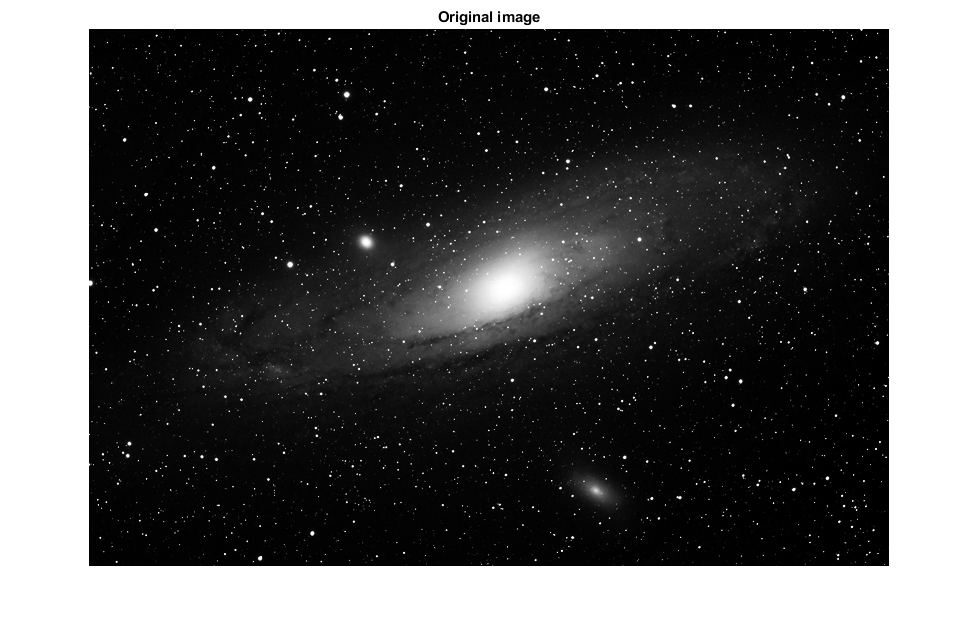

original = imread('galaxy.png');
figure;
imshow(original);
title('Original image');

Paso 2) Creating a structuring element.

se = strel('disk',2);

Paso 3) Top or Bottom Hat.

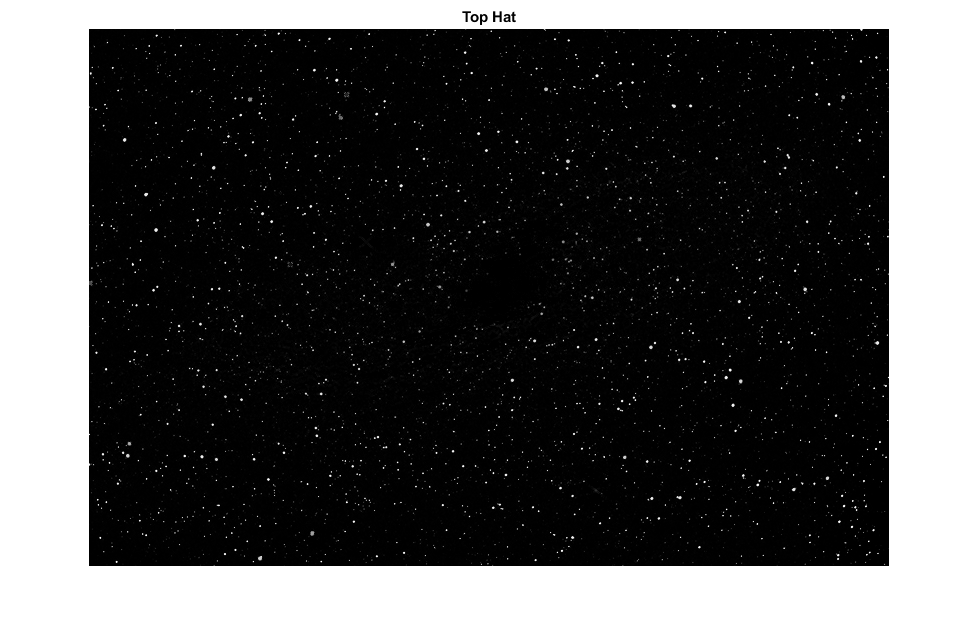

tophat = imtophat(original,se);
figure;
imshow(tophat);
title('Top Hat');

Se pide: 

- Supongamos que sólo nos interesan las pequeñas manchas en la imagen y queremos eliminar la galaxia. La operación (white) top-hat puede eliminar objetos brillantes más grandes y retener pequeñas manchas seleccionando correctamente el tamaño del elemento estructurante. Elija (Paso 2) un elemento estructurante en forma de disco y encuentre el radio que permita mantener todas las estrellas y galaxias pequeñas y eliminar solo la galaxia grande. 

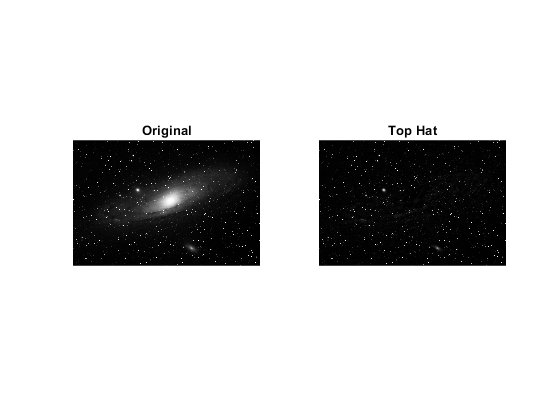

se = strel('disk', 12, 8);

tophat = imtophat(original, se);

figure;
subplot(1,2,1); imshow(original); title('Original');
subplot(1,2,2); imshow(tophat);   title('Top Hat');

         2. Cuando el fondo es blanco y el primer plano es oscuro, debemos cambiar el enfoque. Obtenga la imagen complementada con la función `imcomplement` (1) y compruebe que la operación (white) top-hat no funciona correctamente.     Explique por qué y obtenga una solución.

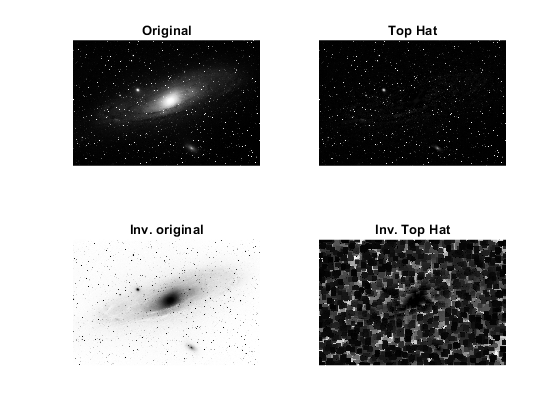

I_inv = imcomplement(original);
tophat_inv = imtophat(I_inv, se);

figure;
subplot(2,2,1); imshow(original);   title('Original');
subplot(2,2,2); imshow(tophat);     title('Top Hat');
subplot(2,2,3); imshow(I_inv);      title('Inv. original');
subplot(2,2,4); imshow(tophat_inv); title('Inv. Top Hat');

***Top Hat***** obtiene los objetos que son más brillantes que sus alrededores y que son "más pequeños" que el elemento estructurante. La solución sería usar *****Bottom Hat*****, ya que esta función obtiene los objetos que son más oscuros que sus alrededores.**

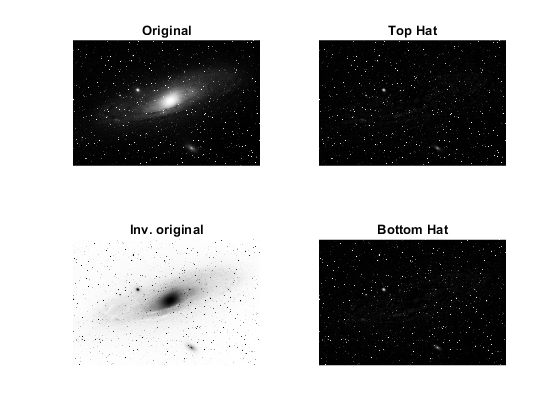

bothat = imbothat(I_inv, se);

figure;
subplot(2,2,1); imshow(original); title('Original');
subplot(2,2,2); imshow(tophat);   title('Top Hat');
subplot(2,2,3); imshow(I_inv);    title('Inv. original');
subplot(2,2,4); imshow(bothat);   title('Bottom Hat');

**Como se puede observar, dependiendo de la imagen de entrada usada, es conveniente usar o *****Top Hat***** o *****Bottom Hat*****.**